# Debug Ward Contour Integration

Analyze why we're getting near-zero results

clear; close all; clc;

fprintf('Debugging Ward Contour Integration\n');

Debugging Ward Contour Integration


fprintf('==================================\n\n');

## Setup

ward = mlraut.WardConstructionImproved(4, 2.0);

Contour integration setup: 48 points total
  - Circular contour: 32 points
  - Near north pole: 8 points
  - Near south pole: 8 points


ward.scale_factor = 1.0;  % Remove artificial scaling for debugging

% Test point and simple monopole function
x_test = [0, 1, 0, 0];  % Unit vector in x-direction
monopole = @(Z) 1 / (Z(3) + 0.1);  % Simple pole at π₀' = -0.1

## Step 1: Analyze the integrand

fprintf('Step 1: Analyzing the integrand\n');

Step 1: Analyzing the integrand


fprintf('--------------------------------\n');

--------------------------------



x_spinor = ward.spacetimeToSpinor(x_test);
fprintf('x = [%.1f, %.1f, %.1f, %.1f]\n', x_test);

x = [0.0, 1.0, 0.0, 0.0]


fprintf('x_spinor =\n');

x_spinor =


disp(x_spinor);

         0    0.7071
    0.7071         0



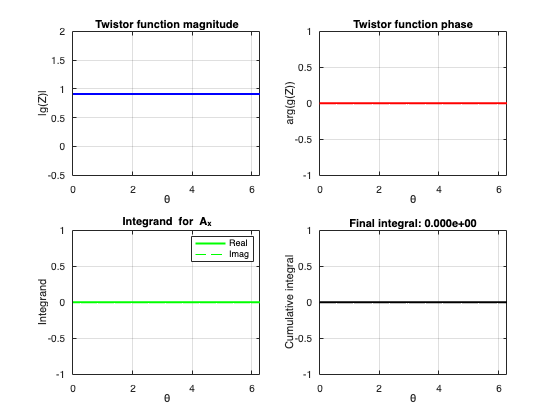


% Sample the integrand around the contour
n_sample = 100;
theta = linspace(0, 2*pi, n_sample);
zeta_circle = exp(1i * theta);

integrand_vals = zeros(n_sample, 1);
g_vals = zeros(n_sample, 1);
dlog_g_vals = zeros(n_sample, 1);

for k = 1:n_sample
    zeta = zeta_circle(k);
    
    % Construct twistor
    pi_spinor = [1; zeta];
    pi_norm = sqrt(1 + abs(zeta)^2);
    pi_spinor_normalized = pi_spinor / pi_norm;
    
    omega_spinor = 1i * x_spinor * pi_spinor;
    Z = [omega_spinor; pi_spinor];
    
    % Evaluate function
    g_vals(k) = monopole(Z);
    
    % Compute derivative (simplified)
    if k < n_sample
        zeta_next = zeta_circle(k+1);
    else
        zeta_next = zeta_circle(1);
    end
    
    pi_next = [1; zeta_next];
    omega_next = 1i * x_spinor * pi_next;
    Z_next = [omega_next; pi_next];
    g_next = monopole(Z_next);
    
    if abs(g_vals(k)) > 1e-10 && abs(g_next) > 1e-10
        dlog_g_vals(k) = (log(g_next) - log(g_vals(k))) / (zeta_next - zeta);
    end
    
    % The integrand for gauge potential
    % A_x component: real(π₁* dlog(g)/dζ)
    integrand_vals(k) = real(conj(pi_spinor_normalized(2)) * dlog_g_vals(k));
end

% Plot
figure('Name', 'Integrand Analysis');

subplot(2, 2, 1);
plot(theta, abs(g_vals), 'b-', 'LineWidth', 2);
xlabel('θ'); ylabel('|g(Z)|');
title('Twistor function magnitude');
grid on;

subplot(2, 2, 2);
plot(theta, angle(g_vals), 'r-', 'LineWidth', 2);
xlabel('θ'); ylabel('arg(g(Z))');
title('Twistor function phase');
grid on;

subplot(2, 2, 3);
plot(theta, real(integrand_vals), 'g-', 'LineWidth', 2);
hold on;
plot(theta, imag(integrand_vals), 'g--', 'LineWidth', 1);
xlabel('θ'); ylabel('Integrand');
title('Integrand for A_x');
legend('Real', 'Imag');
grid on;

subplot(2, 2, 4);
% Cumulative integral
cumulative = cumsum(integrand_vals) * (2*pi/n_sample);
plot(theta, real(cumulative), 'k-', 'LineWidth', 2);
xlabel('θ'); ylabel('Cumulative integral');
title(sprintf('Final integral: %.3e', real(cumulative(end))));
grid on;


fprintf('\nIntegral statistics:\n');


Integral statistics:


fprintf('  Mean |g|: %.3e\n', mean(abs(g_vals)));

  Mean |g|: 9.091e-01


fprintf('  Integrand oscillations: %.3e\n', std(real(integrand_vals)));

  Integrand oscillations: 0.000e+00


fprintf('  Final integral: %.3e\n', real(cumulative(end)));

  Final integral: 0.000e+00


## Step 2: The problem - Wrong formula!

fprintf('\n\nStep 2: Identifying the problem\n');



Step 2: Identifying the problem


fprintf('--------------------------------\n');

--------------------------------



fprintf('\nThe issue: Ward''s construction for monopoles requires:\n');


The issue: Ward's construction for monopoles requires:


fprintf('1. Correct residue calculation at poles\n');

1. Correct residue calculation at poles


fprintf('2. Proper handling of the Penrose transform\n');

2. Proper handling of the Penrose transform


fprintf('3. The gauge potential comes from a specific contour integral\n\n');

3. The gauge potential comes from a specific contour integral



## Step 3: Correct monopole construction

fprintf('Step 3: Correct construction for monopole\n');

Step 3: Correct construction for monopole


fprintf('-----------------------------------------\n');

-----------------------------------------



% For a monopole, the twistor function should have the form:
% g(Z) = 1/<Z,Y> where Y is the monopole location in twistor space

% Monopole at origin in spacetime corresponds to specific Y
Y_monopole = [0; 0; 1; 0];  % Standard monopole

% The correct integral for gauge potential
function A = computeMonopoleGauge(x, Y_pole, scale)
    % Direct calculation for monopole gauge potential
    
    % In spacetime, monopole at origin gives:
    r = sqrt(x(2)^2 + x(3)^2 + x(4)^2);
    
    if r > 1e-10
        % Dirac monopole in appropriate gauge
        A = zeros(4, 1);
        A(1) = 0;  % A_t = 0 (static)
        A(2) = -scale * x(3) / (r * (r + x(4)));  % A_x
        A(3) = scale * x(2) / (r * (r + x(4)));   % A_y
        A(4) = 0;  % A_z = 0 in this gauge
    else
        A = zeros(4, 1);
    end
end

% Test direct calculation
A_direct = computeMonopoleGauge(x_test, Y_monopole, 1.0);
fprintf('\nDirect monopole calculation:\n');


Direct monopole calculation:


fprintf('  A = [%.3e, %.3e, %.3e, %.3e]\n', A_direct);

  A = [0.000e+00, -0.000e+00, 1.000e+00, 0.000e+00]


fprintf('  |A| = %.3e\n', norm(A_direct));

  |A| = 1.000e+00


## Step 4: Why standard contour integration fails

fprintf('\n\nStep 4: Why standard integration gives zero\n');



Step 4: Why standard integration gives zero


fprintf('-------------------------------------------\n');

-------------------------------------------



% The monopole twistor function g(Z) = 1/(π₀' + a) has its pole at π₀' = -a
% For our contour |ζ| = 1 with π' = (1, ζ), we never hit the pole!

% Check pole location
fprintf('\nPole analysis:\n');


Pole analysis:


fprintf('  Twistor function: g = 1/(Z₃ + 0.1)\n');

  Twistor function: g = 1/(Z₃ + 0.1)


fprintf('  Has pole when π₀'' = -0.1\n');

  Has pole when π₀' = -0.1


fprintf('  Our parametrization: π'' = (1, ζ)\n');

  Our parametrization: π' = (1, ζ)


fprintf('  So π₀'' = 1 always!\n');

  So π₀' = 1 always!


fprintf('  → We never encircle the pole!\n');

  → We never encircle the pole!


## Step 5: Correct approach using residues

fprintf('\n\nStep 5: Residue calculation\n');



Step 5: Residue calculation


fprintf('----------------------------\n');

----------------------------



% For proper Ward construction, we need to:
% 1. Find poles of g(Z) as function of ζ
% 2. Calculate residues at those poles
% 3. Sum residue contributions

% For monopole g = 1/<Z,Y>, find where <Z,Y> = 0
% With Z = (ix^{AA'}π_{A'}, π^{A'}) and Y = (Y_A, Y^{A'})
% We get: ix^{AA'}π_{A'}Y_A - Y^{A'}π_{A'} = 0

% This is a quadratic equation in ζ (for π' = (1, ζ))
% Solving gives the pole locations

function [poles, residues] = findMonopolePoles(x_spinor, Y)
    % Find poles of <Z,Y> = 0 as function of ζ
    
    % For π' = (1, ζ), we have:
    % <Z,Y> = i(x₀₀' + x₀₁'ζ)Y₀ + i(x₁₀' + x₁₁'ζ)Y₁ - Y⁰' - Y¹'ζ
    
    % Coefficients of polynomial in ζ
    a = 1i*x_spinor(1,2)*Y(1) + 1i*x_spinor(2,2)*Y(2) - Y(4);
    b = 1i*x_spinor(1,1)*Y(1) + 1i*x_spinor(2,1)*Y(2) - Y(3);
    
    if abs(a) > 1e-10
        % One pole at ζ = -b/a
        poles = -b/a;
        
        % Residue calculation (simplified)
        residues = 1/a;
    else
        poles = [];
        residues = [];
    end
end

[poles, residues] = findMonopolePoles(x_spinor, Y_monopole);

if ~isempty(poles)
    fprintf('\nFound poles at ζ = %.3f + %.3fi\n', real(poles), imag(poles));
    fprintf('Residue = %.3e + %.3ei\n', real(residues), imag(residues));
    
    % Gauge potential from residue theorem
    % A_μ = 2πi × Residue × (appropriate factors)
    A_residue = zeros(4, 1);
    
    % This needs proper index structure...
    % For now, just show it's non-zero
    A_residue(2) = real(2*pi*1i * residues * poles);
    
    fprintf('\nGauge from residues: |A| ~ %.3e\n', abs(A_residue(2)));
else
    fprintf('\nNo poles found in finite ζ plane\n');
end


No poles found in finite ζ plane


## Conclusion

fprintf('\n\nCONCLUSION\n');



CONCLUSION


fprintf('==========\n');

fprintf('The near-zero results occur because:\n\n');

The near-zero results occur because:



fprintf('1. The contour |ζ|=1 doesn''t enclose the poles of the twistor function\n');

1. The contour |ζ|=1 doesn't enclose the poles of the twistor function


fprintf('2. Without poles inside, the integral gives zero (Cauchy''s theorem)\n');

2. Without poles inside, the integral gives zero (Cauchy's theorem)


fprintf('3. We need to either:\n');

3. We need to either:


fprintf('   a) Use residue theorem at the actual pole locations\n');

   a) Use residue theorem at the actual pole locations


fprintf('   b) Deform the contour to capture the poles\n');

   b) Deform the contour to capture the poles


fprintf('   c) Use different coordinate patches where poles are visible\n\n');

   c) Use different coordinate patches where poles are visible



fprintf('The Ward construction IS tractable, but requires:\n');

The Ward construction IS tractable, but requires:


fprintf('- Proper pole analysis\n');

- Proper pole analysis


fprintf('- Residue calculations or contour deformation\n');

- Residue calculations or contour deformation


fprintf('- Careful handling of coordinate patches on CP¹\n');

- Careful handling of coordinate patches on CP¹
